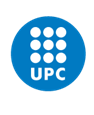

**ESTRUCTURES AEROESPACIALS**

# **Wingbox Structure**

*March 2025*

**Julen Aguilera, Sergio Sanz**

**[Note: The assignment can be done in groups of two people.]**

## **Introduction**

Consider the wingbox of an aircraft modeled as a 1D beam, as depicted in Figure 1. The three-cell wing section consists of two vertical spar webs and the skin, but the loads are supported mainly by the intermediate cell (highlighted in black). The material Young’s modulus is $E=$ 150 GPa and the shear modulus is $G=$ 60 GPa. The geometric parameters in Figure 1 are: $\xi_\text{P} = $ 0.285$c
$, $d=$ 0.34$c$, $t_1=$ 22 mm, $t_2=$ 18 mm, and $t_3=$ 3.5 mm. The beam's cross-sectional area will be modeled by a set of booms and plates. The position and area of the booms is given below (see code section).

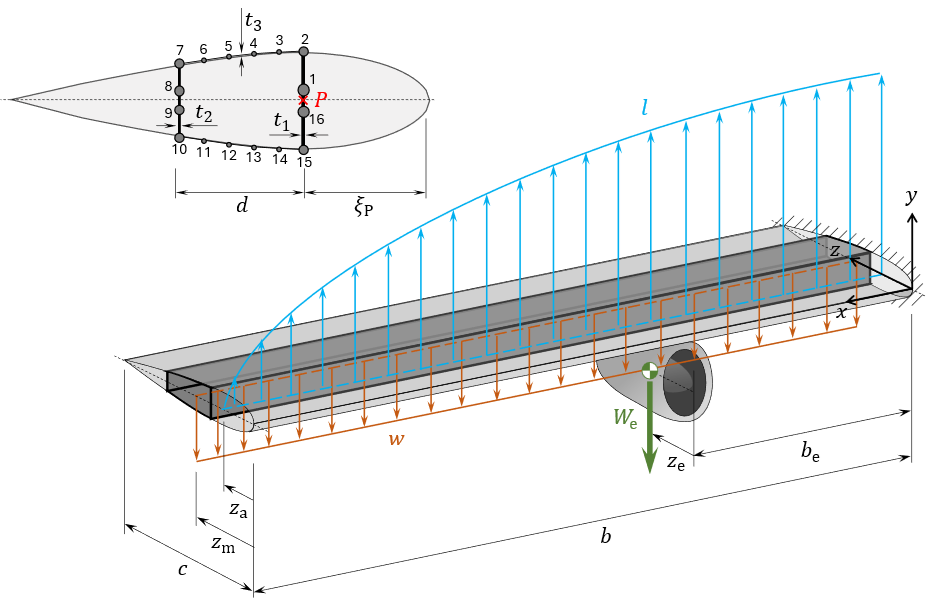

**Figure 1.** Wingbox model of an aircraft wing. Data: chordlength $c = $ 1.5 m, semispan $b = $ 16 m.

The wing is subjected to a distributed lift, $l$, acting along the aerodynamic centre line, located at a distance $z_\text{a}=$ 0.25$c$ from the leading edge. It also supports its own weight, $w$, with a uniformly distributed mass $\lambda = $ 150 kg/m along the centre of mass line, located at a distance $z_\text{m}=$ 0.48$c$. Additionally, the wingh supports the weight of the engine of mass $M_\text{e}=$ 2100 kg at the point depicted in Figure 1, at a distance $b_\text{e}=$ 0.25$b$ from the root section and $z_\text{e}=$ 0.3$c$ from the leading edge. The lift is modeled according to:


$$l(x)=\frac{1}{2} \rho_\infty V_\infty^2 c C_l \sqrt{1-\left(\frac{x}{c}\right)^2$$


where $\rho_\infty =$ 1.225 kg/m${}^3$, $V_\infty=$ 850 km/h, $C_l = $ 0.12. 

The goal of this assignment is to analyse the structural response of the wingbox in two scenarios:

- In standard conditions, when the cross-section along the span is as depicted in Figure 1 (closed).

- In the case where a crack appears near the wing tip, from $x =$ 0.75$b$ to $x = b$, causing the cross-section to be opened at point $P$ (between booms 1 and 16).

### A) Cross-section analysis

First, the following cross-section parameters must be determined:

- The cross-section centroid, $z_0$ measured from the leading edge.

- The shear centre position, $z_\text{S}$ measured from the leading edge.

- The bending inertia, $I_{zz}$.

- The torsional inertia, $J$.    

At this stage, the following results must be obtained:

- The normal stress distribution caused by a unit bending moment, $\sigma|_{M=1}$.

- The shear stress distribution caused by a unit shear load acting on the shear centre, $\tau_\text{s}|_{Q=1}$.

- The shear stress distribution caused by a unit torsion moment, $\tau_\text{t}|_{T=1}$.

This analysis must be done for both the **open** and **closed** section cases.

Hint: The following formulas can be used to approximate the torsional inertia:


$$J_\text{open} = \sum_i \frac{s_i t_i^3}{3}$$



$$\sum_i \frac{s_i}{t_i} = \frac{4 A_\text{in}^2}{J_\text{closed}}$$


where $s_i$ is the arc-length of each plate segment in the cross-section, $t_i$ the thickness, and $A_\text{in}$ is the area enclosed within the cross-section.

### B) Beam analysis

Then, a beam discretization must be performed to numerically compute:

- Vertical deflection at the beam's centroid along the span.

- Section bending angle along the span.

- Section twist angle along the span.

- Shear force at the shear centre along the span.

- Bending moment along the span.

- Torsion moment along the span.

To study the convergence of the numerical solution, the analysis must be repeated for different number of elements: $n_\text{ele} =$ {4, 8, 16, 32, 64, 128}. The results will be compared with a reference case with $n_\text{ele}^\text{ref}=$ 512 elements by measuring the error according to:


$$\epsilon = \left|{\frac{u(b)|_{n_\text{ele}}-u(b)|_{n_\text{ele}^\text{ref}}}{u(b)|_{n_\text{ele}^\text{ref}}}}\right|$$


where $u(b)$ is the deflection at the wing tip. A plot of the error vs. the number of elements in logarithmic scale must be obtained.

This analysis must be done for both the scenarios (standard conditions and with the crack near the tip).

### C) Von Mises analysis

Finally, the Von Mises criterion must be applied to locate the most critical point in the interior of the wing's structure in both scenarios (standard conditions and with the crack near the tip). With the bending moment, $M(x)$, shear force at the shear centre $Q(x)$, and torsion moment $T(x)$ distributions along the span, using the precomputed normal and shear stress distributions for unit loads over the cross-sections, $\sigma|_{M=1}$, $\tau_\text{s}|_{Q=1}$, and $\tau_\text{t}|_{T=1}$, it is possible to obtain the Von Mises stress as:


$$\sigma_\text{VM}(x,s) = \sqrt{\left(\sigma|_{M=1}(s)M(x)\right)^2+3\left(\tau_\text{s}|_{Q=1}(s)Q(x)+\tau_\text{t}|_{T=1}(s)T(x)\right)^2}$$


## Results

### **A) Cross-section analysis**

[Write here the code to produce the requested results, or, alternatively, explain the analytical approach used]

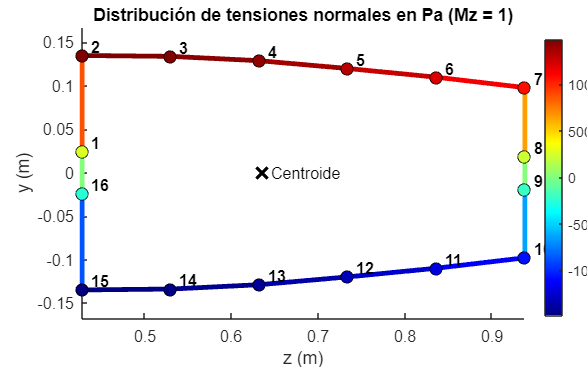

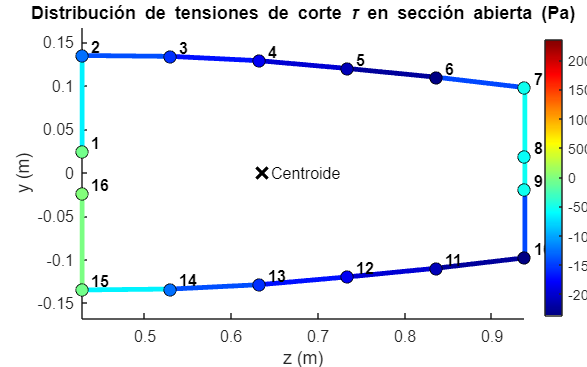

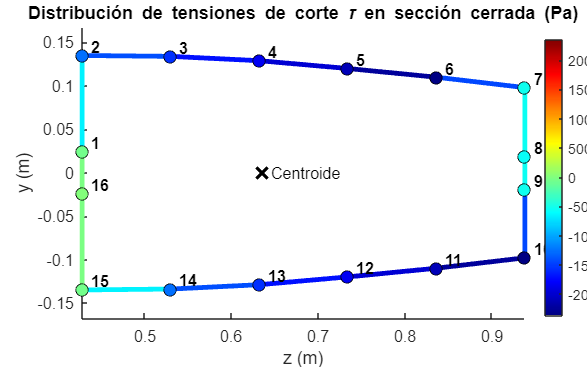

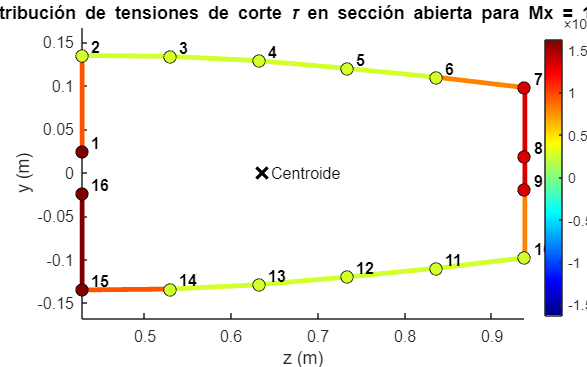

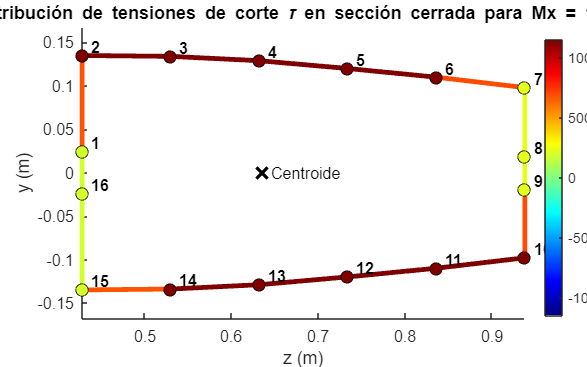

clear % Clear workspace

% Booms distribution over the cross-section
% First column: z coordinate (in mm) with respect to airfoil leading edge
% Second column: y coordinate (in mm)
% Third column: area (in mm^2)
data.booms = [
    428	24	    2225.9 
    428	135	    920.5  
    530	134	    357.2
    632	129	    357.8
    734	120	    358.5
    836	110	    359.3
    938	98	    530.9
    938	19	    1404.1
    938	-19	    1404.1
    938	-98	    530.9
    836	-110	359.3
    734	-120	358.5
    632	-129	357.8
    530	-134	357.2
    428	-135	920.5
    428	-24	    2225.9
];

% Pasar unidades de booms a SI
data.booms = data.booms/1000;
data.booms(:,3) = data.booms(:,3)/1000;

data.g = 9.81;
data.E = 150e9; 
data.G = 60e9;
data.c = 1.5;
data.b = 16;
data.d = 0.34*data.c;
data.t1 = 22e-3;
data.t2 = 18e-3;
data.t3 = 3.5e-3;
data.za = 0.25*data.c;
data.lambda = 150; 
data.zm = 0.48*data.c;
data.Me = 2500;
data.be = 0.25*data.b;
data.ze = 0.3*data.c;
data.ro = 1.225; 
data.V = 850/3.6; 
data.Cl = 0.12;
data.Xrotura = 0.75*data.b;
data.xi = 0.285*data.c;
data.t = [data.t1 data.t2 data.t3];

% ------------- Analisis de la sección --------------------

[xboom,Tboom,Tmat,data] = section_analysis(data);
% Centroide, inercia, módulos de torsión (Jopen y Jclosed):
data = section_precalcs(data,xboom,Tboom,Tmat); % Se obtiene una inercia Izy ~ 0

% Cálculo del qopen y el centro de torsión 
data = shear_open(data,xboom,Tmat,Tboom);

% Cálculo del q0 y qclosed. Antes hay que situar el punto de aplicación del
% Sy
data.coordSy = data.sc;           % Punto de aplicación del Sy visto des del LE
[data.q0,data.qclosed] = shear_closed(data);

% Graficado 
graficas_seccion(data,Tmat)

### B) Beam analysis 

[Write here the code to produce the requested results] 

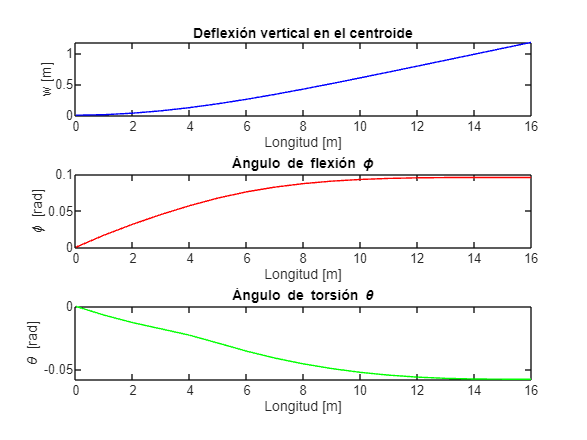

nel = 16;
[data, xnod, Tnod, mat,fixnod] = beam_precalcs (data, nel);

% --------- SIN ROTURA EN EL PERFIL DEL ALA ----------

data.roto = false;
[M, S, T, disp, w_centroid, theta_flex, theta_torsion] = beam_analysis (data, xnod, Tnod, mat, fixnod);
figure
subplot(3,1,1);
plot(xnod(:,1), w_centroid, 'b');
title('Deflexión vertical en el centroide');
xlabel('Longitud [m]'); ylabel('w [m]');

subplot(3,1,2);
plot(xnod(:,1), theta_flex, 'r');
title('Ángulo de flexión \phi');
xlabel('Longitud [m]'); ylabel('\phi [rad]');

subplot(3,1,3);
plot(xnod(:,1), theta_torsion, 'g');
title('Ángulo de torsión \theta');
xlabel('Longitud [m]'); ylabel('\theta [rad]');

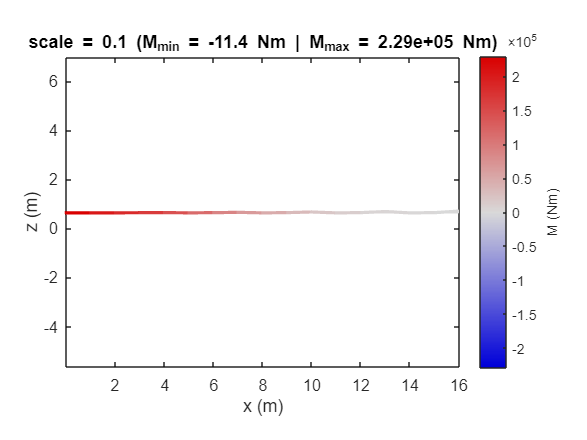


% Momento flector a lo largo de la barra
figure;
plotEsfuerzoBarra2D(xnod, Tnod, disp, mean(M), 0.1, 'Nm', 'M');

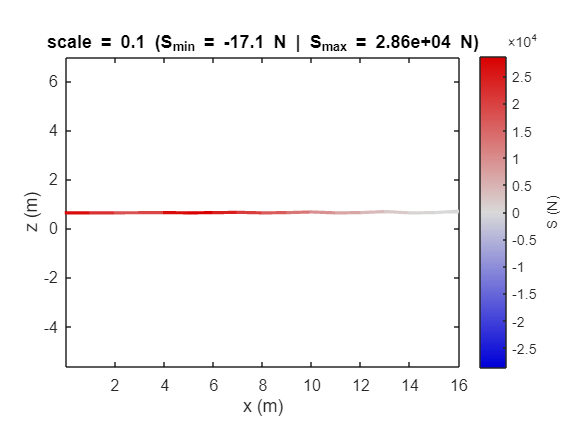

% Esfuerzo cortante a lo largo de la barra
plotEsfuerzoBarra2D(xnod, Tnod, disp, mean(S), 0.1, 'N', 'S');

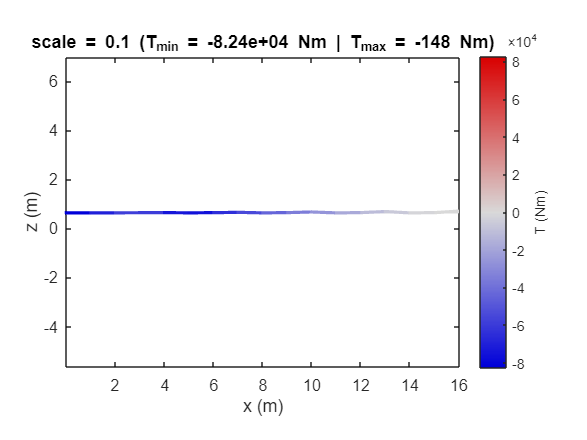

% Momento torsor a lo largo de la barra
plotEsfuerzoBarra2D(xnod, Tnod, disp, mean(T), 0.1, 'Nm', 'T');

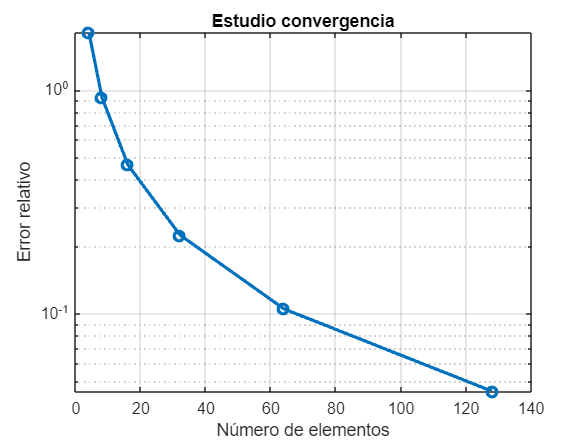

estudio_convergencia(data)

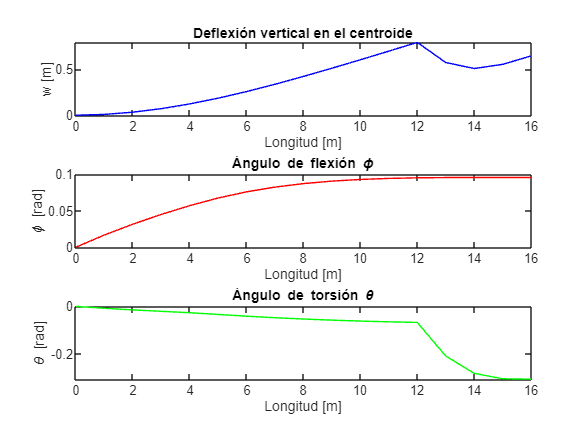


momentos(:,1) = mean(M).';
shear(:,1) = mean(S).';
torsion(:,1) = mean(T).';

% ---------------- ROTURA EN EL PERFIL DEL ALA --------------------

data.roto = true;
[M, S, T, disp, w_centroid, theta_flex, theta_torsion] = beam_analysis (data, xnod, Tnod, mat, fixnod);

figure
subplot(3,1,1);
plot(xnod(:,1), w_centroid, 'b');
title('Deflexión vertical en el centroide');
xlabel('Longitud [m]'); ylabel('w [m]');

subplot(3,1,2);
plot(xnod(:,1), theta_flex, 'r');
title('Ángulo de flexión \phi');
xlabel('Longitud [m]'); ylabel('\phi [rad]');

subplot(3,1,3);
plot(xnod(:,1), theta_torsion, 'g');
title('Ángulo de torsión \theta');
xlabel('Longitud [m]'); ylabel('\theta [rad]');

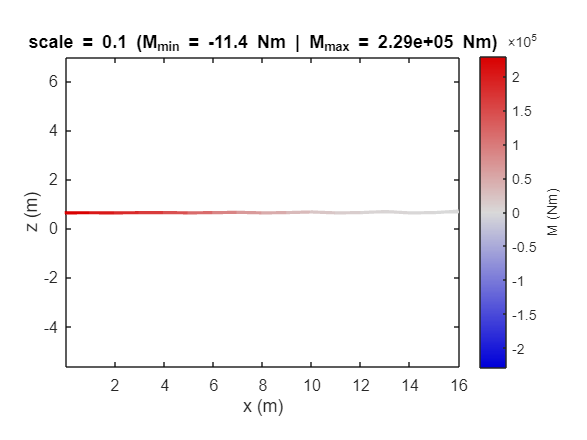

figure;
% Momento flector a lo largo de la barra
plotEsfuerzoBarra2D(xnod, Tnod, disp, mean(M), 0.1, 'Nm', 'M');

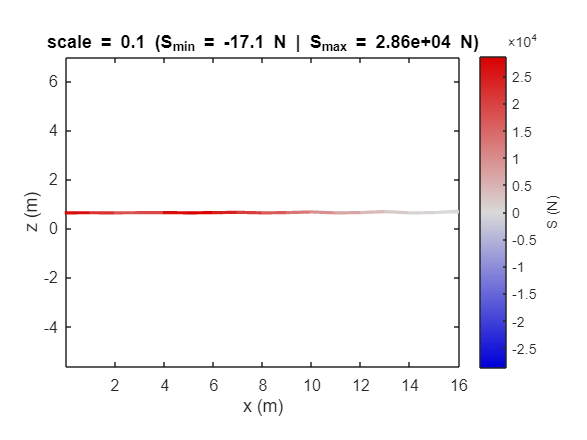

% Esfuerzo cortante a lo largo de la barra
plotEsfuerzoBarra2D(xnod, Tnod, disp, mean(S), 0.1, 'N', 'S');

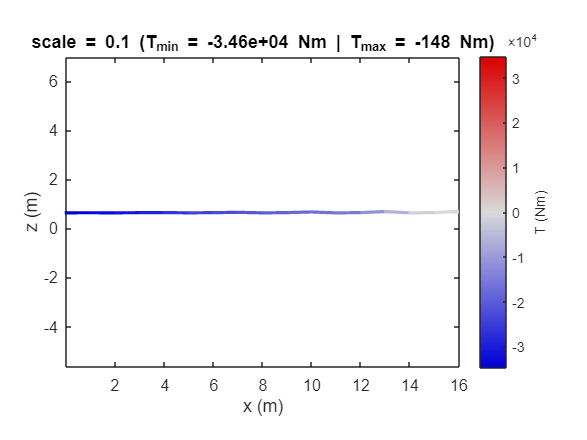

% Momento torsor a lo largo de la barra
plotEsfuerzoBarra2D(xnod, Tnod, disp, mean(T), 0.1, 'Nm', 'T');

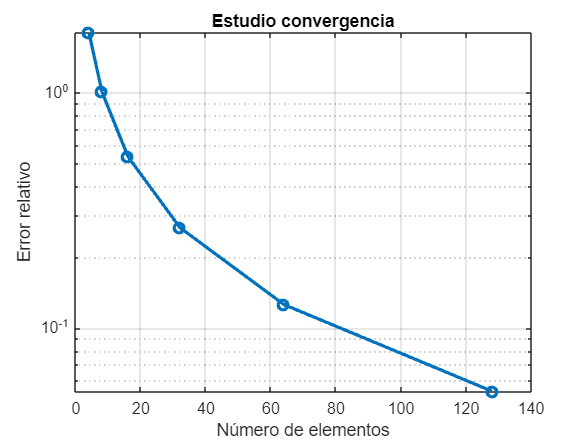

estudio_convergencia(data)


momentos(:,2) = mean(M).';
shear(:,2) = mean(S).';
torsion(:,2) = mean(T).';

### C) Von Mises analysis

[Write here the code to produce the requested results]

% Entradas físicas (momentos flectores, momentos torsores y esfuerzos
% cortantes) ---> vectores de nel x 2 
% nel x 2    
% columna 1: correspondientes al caso en el que no se rompe
% columna 2: correspondientes al caso en el que se rompe 

sigmaVM = von_mises(data,Tmat,xnod,momentos,shear,torsion);

tablasVM(data,sigmaVM);

---------------------------------------------------------
σ_VM críticas:


    Estado de la sección    Magnitud critica (MPa)    Boom critico    Nodo
    ____________________    ______________________    ____________    ____

        "Sin romper"                344.88                 3           1  
        "Rota"                      344.56                 3           1  



---------------------------------------------------------
σ_VM críticas para cada elemento cuando la sección se rompe:


    Magnitud critica (MPa)    Boom critico    Nodo
    ______________________    ____________    ____

            344.56                  3           1 
            305.55                  2           2 
            273.91                  2           3 
            248.19                  3           4 
            223.11                  3           5 
            188.17                  4           6 
            148.13                  4           7 
            115.36                  6           8 
             88.29                  6           9 
            65.321                  6          10 
             46.15                  6          11 
            30.478                  6          12 
            326.52                 15          13 
            167.83                 15          14 
             53.15                 15          15 
            4.1726            

---------------------------------------------------------
σ_VM críticas para cada elemento cuando la sección no se rompe:


    Magnitud critica (MPa)    Boom critico    Nodo
    ______________________    ____________    ____

             344.88                3            1 
             305.74                2            2 
             274.03                2            3 
             248.39                3            4 
              223.6                3            5 
             188.95                4            6 
             148.83                4            7 
             116.11                6            8 
             88.883                6            9 
             65.748                6           10 
             46.406                6           11 
             30.563                6           12 
             17.964                6           13 
             8.4616                6           14 
             2.1731                6           15 
           0.066807           

---------------------------------------------------------


## Discussion

[Add a discussion of the results and summarize the main conclusions]

#### **A) Cross-section analysis**

A partir del análisis de la sección se ha podido calcular el centroide, el centro de cortante, las inercias y los esfuerzos provocados por cargas unitarias. En las gráficas de los esfuerzos para los diferentes casos, se puede observar que la principal diferencia entre la sección cerrada y la sección abierta ocurre cuando se aplica un momento torsor. Con la sección abierta, los esfuerzos se concentran en las paredes laterales mientras que con la sección cerrada estos se encuentran en las partes superior e inferior de la sección. Estos resultados se deben por aplicar la fuerza cortante Sy en el centro de cortante, por lo que no se generan esfuerzos cortantes "extras", y por consiguiente, al no tener que añadir el valor asociado al momento torsional  ($q_{s,0}
$), el flujo cortante para sección abierta es igual al de sección cerrada. De esta forma, el unico cambio apreciable para las tensiones cortantes se encuentran unicamente para las correspondientes a los momentos torsores, como ya se ha dicho antes. Esto se debe a que la carga se distribuye de manera más uniforme a lo largo de la sección para un perfil cerrado.

#### B) Beam analysis 

Para el análisis del ala se ha utilizado la aproximación 1D, utilizando 3 grados de libertad en cada nodo (desplazamiento vertical, ángulo de flexión y ángulo de torsión). Para ello se han reutilizado partes del código de la práctica *A02_solar_sail *adaptandolo a los grados de libertad de este problema. 

En el caso del ala sin rotura, el comportamiento de la deflexión vertical del centroide es el que se espera de un ala que está generando sustentación ya que esta fuerza tiende a curvar el ala hacia arriba. El ángulo de flexión crece con la longitud, pero al acercarse a la punta se va estabilizando porque el momento flector cae a cero y por tanto la rotación deja de aumentar. El ángulo de torsión tiene el comportamiento opuesto al del ángulo de flexión, se hace más pequeño con la longitud y se acaba estabilizando. Este efecto se conoce como *wash-out *y también es algo tipico en un ala ya que se hace para reducir el ángulo de ataque en la punta y así retrasar la entrada en pérdida. 

En el caso del ala con rotura, se observa un comportamiento idéntico entre el empotramiento y la rotura, pero después de ese punto, la deflexión vertical del centroide y el ángulo de torsión se reducen. El ángulo de flexión sin embargo se mantiene igual.

Al mostrar las gráficas de los momentos de flexión y torsión, así como el esfuerzo cortante, se puede observar que el modelo del ala tiene unos desplazamientos que no coinciden con lo esperado, ya que hacen una especie de zig-zag. Esto sugiere que hay algún error en el cálculo de los desplazamientos, pero no hemos sido capaces de encontrarlo.

En ambos casos, con y sin rotura, la solución parece que converge si se compara con el caso de referencia de 512 elementos, ya que el error relativo es cada vez más pequeño a medida que aumenta el número de elementos utilizado.

#### C) Von Mises analysis

Una vez realizado el análisis del ala, se utilizan los resultados obtenidos para los casos con los elementos seleccionados en *nel* para calcular los módulos de las tensiones resultantes mediante Von Mises. Este estudio permite obtener tanto las tensiones máximas, como el nodo crítico para la sección transversal de cada elemento para así realizar un posterior estudio de los materiales con los que se ha de construir el ala, ajustándose a una tensión admisible máxima.

Fijándonos en las tablas de tensiones obtenidas, se puede observar que la tensión máxima obtenida para todo el ala para el caso en el que la sección no se rompe. Analizando elemento a elemento, se puede observar que para el caso en el que la sección se rompe, las magnitudes son menores en la zona que no está afectada. Sin embargo, cuando se alcanza la zona en que la sección se abre, se observa un aumento notable de la tensión obtenida, de hasta dos órdenes de magnitud más que para el caso en el que no se rompe.

De estos resultados podemos concluir que, en primer lugar, el nodo crítico para ambos casos es el correspondiente al empotramiento ala-fuselaje, por lo que es el que debe ser mejor reforzado, ya que será el primero en fallar. En segundo lugar, también se puede notar que cuando no hay fisuras en el esqueleto del avión, las tensiones se reparten de manera que cerca del empotramiento se concentren la mayoría, y que en la punta del ala no haya casi tensiones. Sin embargo, con la presencia de fisuras en el esqueleto, el reparto de estas tensiones no se realiza de la forma esperada, disminuyendo así las fuerzas en el empotramiento y en las zonas sin romper, y aumentándolas en las zonas afectadas.

## Code functions

Create your own functions.

# SECTION ANALYSIS 

- Análisis previo de la sección para su posteior operación 

function [xboom,Tboom,Tmat,data] = section_analysis(data)

% Nodal coordinates
xboom = zeros(length(data.booms),2);
xboom(:,1) = data.booms(:,1); xboom(:,2) = data.booms(:,2); 

% Nodal connectivities
Tboom = [
    1 2
    2 3
    3 4
    4 5
    5 6
    6 7
    7 8
    8 9
    9 10
    10 11
    11 12
    12 13
    13 14
    14 15
    15 16
    16 1 
];

% Material connectivities
Tmat = [
    1
    3
    3
    3
    3
    3
    2
    2
    2
    3
    3
    3
    3
    3
    1
    1
];

% Problem dimensions
data.nboom = size(xboom,1);
data.nskin = size(Tboom,1);



end

- *Cálculos previos para la sección *

function data = section_precalcs(data,xnod,Tboom,Tmat)

% --------------------- CENTROIDE -------------------------

At = sum(data.booms(:,3)); % Area total de los booms
sumay = 0;
sumaz = 0;

for i = 1:length(data.booms)  % Sumatorio de area*distancia al LE
    sumay = data.booms(i,2)*data.booms(i,3)+sumay;  
    sumaz = data.booms(i,1)*data.booms(i,3)+sumaz;
end

y_centroide = sumay/At;
z_centroide = sumaz/At;

data.centroide = [z_centroide y_centroide];

% ------------------ INERCIAS -------------------------

% Inicializar las variables de inercia
iz = 0;
iy = 0;
izy = 0; 

% Iterar sobre los elementos de data.booms
for i = 1:length(data.booms)
    % Calcular la inercia alrededor del eje Z
    iz = iz + (data.booms(i,2) - data.centroide(2))^2 * data.booms(i,3);
    
    % Calcular la inercia alrededor del eje Y
    iy = iy + (data.booms(i,1) - data.centroide(1))^2 * data.booms(i,3);
    
    % Calcular el término de producto de inercia
    izy = izy + (data.booms(i,1) - data.centroide(1)) * (data.booms(i,2) - data.centroide(2)) * data.booms(i,3);
end

% Guardar el resultado de las inercias en la estructura

data.inercia = [iz, iy, izy];

% ------------------ INERCIA TORSIONAL ------------------------

J = 0; suma = 0; 
data.long_section = longitud_elementos(xnod, Tboom, data.nskin);
long = data.long_section;
for i = 1:data.nskin
    J = J + 1/3*long(i)*data.t(Tmat(i))^3;
    suma = suma + data.long_section(i)/data.t(Tmat(i));
end

data.Ain = area_interior(xnod);
data.Jopen = J; 
data.Jclose = 4*data.Ain^2/suma;

end

- * Flujo cortante para sección abierta y centro de torsión*

function data = shear_open(data,xnod,Tmat,Tboom)
Iz = data.inercia(1); Iy = data.inercia(2);
long = data.long_section;

% Sabiendo que My = 0, la distribucion de tensiones axiales irá de la
% siguiente forma:  sigma_x = Mz/Iz * y
% De esta forma, el cuociente de tensiones axiales será igual al cuociente
% entre altura de los booms 
% Suponiendo que Sy = 1, y sabiendo que el centroide en la cordenada y es
% 0 por simteria: 

% ----------------------- QOPEN ------------------------

B_barra = zeros(length(data.booms),1);
for i = 1:data.nskin
    B_barra(Tboom(i,1)) = B_barra(Tboom(i,1))+1/6*data.t(Tmat(i))*long(i)*(2+data.booms(Tboom(i,2),2)/data.booms(Tboom(i,1),2));
    B_barra(Tboom(i,2)) = B_barra(Tboom(i,2))+1/6*data.t(Tmat(i))*long(i)*(2+data.booms(Tboom(i,1),2)/data.booms(Tboom(i,2),2));
end

B = B_barra + data.booms(:,3);

qopen = zeros(data.nskin,1);
qopen(1) = - B(1)*xnod(1,2)/Iz;

for i = 2:data.nskin
    qopen(i) = qopen(i-1) - B(i)*xnod(i,2)/Iz;
end

data.qopen = qopen;

% ----------------- CENTRO DE TORSIÓN -----------------------

% Cálculo de la distancia entre el LE y el nodo 

dist(:,1) = xnod(:,1); %- data.centroide(1)*ones(data.nskin,1);  % (este caso es para verlo des del centroide)
dist(:,2) = xnod(:,2);

% Cálculo del vector longitud para cada elemento 

longitud = zeros(data.nskin,2);
for i = 1:data.nskin
    longz = xnod(Tboom(i,2),1) - xnod(Tboom(i,1),1);
    longy = xnod(Tboom(i,2),2) - xnod(Tboom(i,1),2);
    longitud(i,:) = [longz longy];
end

% Cálculo del centro de torsion 

integral = 0; 
for i = 1:data.nskin
    prod = cross2D(dist(i,:),longitud(i,:));
    integral = integral + prod*qopen(i);
end

SC = integral;

data.sc = [SC 0];

end 

- *Cálculo de q0 y qclosed*

function [q0, qclosed] = shear_closed(data)

% --------------------- Q0 Y QCLOSED ------------------

Ain = data.Ain;

Sy = [0 1]; % Se supone que Sy = 1 N
r = [data.coordSy(1) data.coordSy(2)]; % Vector distancia visto des del LE (origen de coordenadas)

momento_ext = cross2D(r,Sy);
momento_qopen = cross2D(data.sc,Sy);

q0 = (momento_ext - momento_qopen)/2/Ain;

qclosed = data.qopen + q0;

end


# Beam Analysis

- Cálculos previos para el análisis de la viga

function [data, xnod, Tnod, mat, fixnod] = beam_precalcs (data, nel)

data.nnod = nel + 1;
data.ni = 3;
data.nel = nel;
data.nne = 2;
data.ndof = data.nnod*data.ni;
data.nde = data.nne*data.ni;


dx = data.b / nel;
xnod = [(0:nel).' * dx, ones(nel + 1, 1)*data.centroide(1)];        % Col.1: coord.X      Col2: coord.Z
Tnod = [(1:nel).' (2:nel+1).'];


mat = [data.E, data.G, data.inercia(1), data.Jclose, data.Jopen, data.centroide(1), data.sc(1)];

fixnod = [
    1 1 0;  % uy
    1 2 0;  % θz
    1 3 0;  % θx
];

end

- Solver para la viga

function [M, S, T, disp, w_centroid, theta_flex, theta_torsion] = beam_analysis(data, xnod, Tnod, mat, fixnod)

long = longitud_elementos(xnod, Tnod, data.nel);
Kel = zeros(data.nde, data.nde, data.nel);    
fel = zeros(data.nde, data.nel);            
K = zeros(data.ndof); 
f = zeros(data.ndof, 1);

% Geometría de la sección
x0 = mat(6); 
xs = x0;

T = [ 1  0  x0-xs  0   0   0;
      0  1   0     0   0   0;
      0  0   1     0   0   0;
      0  0   0     1   0  x0-xs;
      0  0   0     0   1   0;
      0  0   0     0   0   1 ];

lift = zeros(data.nnod, 1);
peso = zeros(data.nnod, 1);
for i = 1:data.nnod
    lift(i) = 0.5 * data.ro * data.V^2 * data.c * data.Cl * sqrt(1 - (xnod(i,1)/data.b)^2);
end
masanod = masas_nodos(data, Tnod, long);
peso = masanod * data.g;

x_motor = 0.25 * data.b;
[~, idx_cercano] = min(abs(xnod(:,1) - x_motor));
peso(idx_cercano) = peso(idx_cercano) + data.Me * data.g;

x_L = 0.25 * data.c;
x_W = 0.48 * data.c;
x_s = mat(7);

lift_fun = @(x) interp1(xnod(:,1), lift, x, 'linear', 0);
peso_fun = @(x) interp1(xnod(:,1), peso, x, 'linear', 0);
q_fun = @(x) lift_fun(x) - peso_fun(x);

L_bar = zeros(data.nel, 1); 
W_bar = zeros(data.nel, 1); 
q_bar = zeros(data.nel, 1);

for i = 1:data.nel
    x1 = xnod(i,1);
    x2 = xnod(i+1,1);
    L_bar(i) = (1/long(i)) * integral(lift_fun, x1, x2);
    W_bar(i) = (1/long(i)) * integral(peso_fun, x1, x2);
    q_bar(i) = (1/long(i)) * integral(q_fun, x1, x2);
end

m_s = L_bar * (x_L - x_s) + (-W_bar) * (x_W - x_s);

E = mat(1); G = mat(2); Iz = mat(3); J = mat(4);
cumplido = false;

for i = 1:data.nel
    if ~cumplido && data.roto && xnod(i,1) >= data.Xrotura
        J = mat(5);
        xs = mat(7);
        T = [ 1  0  x0-xs  0   0   0;
              0  1   0     0   0   0;
              0  0   1     0   0   0;
              0  0   0     1   0  x0-xs;
              0  0   0     0   1   0;
              0  0   0     0   0   1 ];
        cumplido = true;
    end

    L = long(i);

    k_loc = E*Iz/L^3 * [
        12,      6*L,     0,    -12,      6*L,     0;
        6*L,  4*L^2,     0,   -6*L,   2*L^2,     0;
        0,      0,     0,      0,       0,     0;
       -12,    -6*L,     0,     12,     -6*L,     0;
        6*L,  2*L^2,     0,   -6*L,   4*L^2,     0;
        0,      0,     0,      0,       0,     0];

    kt_loc = G*J/L * [
        0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0;
        0, 0, 1, 0, 0, -1;
        0, 0, 0, 0, 0, 0;
        0, 0, 0, 0, 0, 0;
        0, 0, -1, 0, 0, 1];

    fe_loc = [0.5; L/12; 0; 0.5; L/12; 0];
    ft_loc = [0; 0; 0.5; 0; 0; 0.5];

    Kel(:,:,i) = T.' * (k_loc + kt_loc) * T;
    fel(:,i) = T.' * (q_bar(i)*L * fe_loc + m_s(i)*L * ft_loc);
end

Tdof = data.ni*(repelem(Tnod,1,data.ni)-1) + repmat(1:data.ni,size(Tnod));

for e = 1:data.nel
    I = Tdof(e,:);
    f(I) = f(I) + fel(:,e);
    K(I,I) = K(I,I) + Kel(:,:,e);
end

u = zeros(data.ndof,1); 
vr = zeros(size(fixnod,1), 1);
for i = 1:length(fixnod)
    I = data.ni*(fixnod(i,1)-1) + fixnod(i,2);
    vr(i) = I;
    u(I) = fixnod(i,3);
end

vf = setdiff(1:data.ndof, vr);
u(vf) = K(vf,vf) \ (f(vf) - K(vf,vr) * u(vr));

fint = zeros(6, data.nel);
for e = 1:data.nel
    I = Tdof(e,:);
    fint(:,e) = Kel(:,:,e) * u(I);
end

M = zeros(2,data.nel); S = zeros(2,data.nel); T = zeros(2,data.nel);
for e = 1:data.nel
    M(:,e) = [-fint(2,e); fint(5,e)];
    S(:,e) = [-fint(1,e); fint(4,e)];
    T(:,e) = [-fint(3,e); fint(6,e)] + (xs - x0).*S(:,e);
end

% RESULTADOS NODALES
nnod = data.nnod;
w_centroid    = zeros(nnod,1);
theta_torsion = zeros(nnod,1);
theta_flex    = zeros(nnod,1);

for i = 1:nnod
    base = data.ni*(i-1); 
    w_centroid(i)    = u(base + 1);  % deflexión vertical (uy)
    theta_flex(i)    = u(base + 2);  % giro por flexión (θz)
    theta_torsion(i) = u(base + 3);  % giro por torsión (θx)
end

disp = u;

end


function plotEsfuerzoBarra2D(xnod, Tnod, u, esfuerzo, scale, units, esfuerzoLabel)
% Entradas:
%   xnod         : nnod x 2 matriz de coordenadas nodales [x, z]
%   Tnod         : nel x 2 matriz de conectividades (nodo_i, nodo_f)
%   u            : vector de desplazamientos [ux1; uz1; ux2; uz2; ...]
%   esfuerzo     : vector nel x 1 con valores del esfuerzo (uno por barra)
%   scale        : escala visual para la deformada
%   units        : string de unidades (por ej. 'kNm')
%   esfuerzoLabel: string del tipo de esfuerzo ('Momento flector', etc.)

    X = xnod(:,1);
    Z = xnod(:,2);
    Ux = scale * u(1:2:end);
    Uz = scale * u(2:2:end);
    smin = min(esfuerzo);
    smax = max(esfuerzo);
    nel = size(Tnod,1);

    figure; hold on; axis equal; box on;

    % === Estructura sin deformar (gris claro) ===
    plot(X(Tnod')', Z(Tnod')', '-', 'Color', 0.85*[1,1,1], 'LineWidth', 1);

    % === Estructura deformada con mapa de colores ===
    for e = 1:nel
        n1 = Tnod(e,1);
        n2 = Tnod(e,2);

        x_def = [X(n1) + Ux(n1), X(n2) + Ux(n2)];
        z_def = [Z(n1) + Uz(n1), Z(n2) + Uz(n2)];
        c = [esfuerzo(e), esfuerzo(e)];

        patch(x_def, z_def, c, ...
              'EdgeColor', 'interp', ...
              'LineWidth', 2);
    end

    % === Colormap y colorbar personalizados ===
    clim_max = max(abs([smin, smax]));
    clim([-clim_max, clim_max]);
    colormap(interpolatedColormap());
    cb = colorbar;
    cb.Label.String = sprintf('%s (%s)', esfuerzoLabel, units);

    % === Etiquetas ===
    title(sprintf('scale = %.2g (%s_{min} = %.3g %s | %s_{max} = %.3g %s)', ...
        scale, esfuerzoLabel, smin, units, esfuerzoLabel, smax, units));
    xlabel('x (m)');
    ylabel('z (m)');
end


function estudio_convergencia (data)

    % Definir los diferentes números de elementos para el estudio de convergencia
    num_elem = [4, 8, 16, 32, 64, 128];
    nel_ref = 512; % Número de elementos de referencia para el cálculo de convergencia

    % === Caso de referencia con 512 elementos ===
    % Llamamos a beam_precalcs para obtener los datos del modelo
    [data, xnod_ref, Tnod_ref, mat_ref, fixnod_ref] = beam_precalcs(data, nel_ref);
    % Luego usamos beam_analysis para obtener los desplazamientos
    [~, ~ , ~ , u_ref] = beam_analysis(data, xnod_ref, Tnod_ref, mat_ref, fixnod_ref);
    % Calculamos la deflexión de la punta para el caso de referencia (por ejemplo, último nodo)
    def_ref = u_ref(end);  % Asumiendo que la deflexión está en el último nodo

    % Inicializamos el vector de errores relativos
    errores = zeros(size(num_elem));

    % === Evaluar para cada número de elementos ===
    for i = 1:length(num_elem)
        nel = num_elem(i);
        
        % Llamamos a beam_precalcs para obtener los datos para el número actual de elementos
        [data, xnod, Tnod, mat, fixnod] = beam_precalcs(data, nel);
        
        % Llamamos a beam_analysis para obtener los desplazamientos para el número actual de elementos
        [~, ~, ~, u] = beam_analysis(data, xnod, Tnod, mat, fixnod);
        
        % Calculamos la deflexión para el número actual de elementos
        def = u(end);  % Asumiendo que la deflexión está en el último nodo
        
        % Calculamos el error relativo de la deflexión
        errores(i) = abs((def - def_ref) / def_ref);
    end

    % === Plot semilogy (escala logarítmica en Y) ===
    figure;
    semilogy(num_elem, errores, '-o', 'LineWidth', 2);
    grid on;
    title('Estudio convergencia');
    xlabel('Número de elementos');
    ylabel('Error relativo');
end


# Von Mises

function sigmaVM = von_mises(data,Tmat,xnod,M,S,T)

% Esfuerzos cortantes: el qopen siempre será el mismo a lo largo de la sección,
% pero el qclosed dependerá del punto de aplicación de la fuerza. Como
% consideramos que la fuerza se aplica en el centro de torsión, el qclosed
% será igual que el qopen

q = data.qopen;
tauS = q./data.t(Tmat).';

% Esfuerzos cortantes por momento torsor

tauT_open = data.t(Tmat).'/data.Jopen;
tauT_closed = data.t(Tmat).'/data.Jclose;

% Esfuerzos axiales: la distribucion a lo largo de la seccion dependerá de
% la altura del boom 

Iz = data.inercia(1);
sigma = 1/Iz*data.booms(:,2);

for i = 1:data.nel
    xm = 0.5*(xnod(i,1)+xnod(i+1,1)); 
    % xm para saber a partir de cuando se cuenta como rotura 

    if xm >= data.Xrotura
        tau_open = tauS*S(i,2) + tauT_open*T(i,2);
    else
        tau_open = tauS*S(i,2) + tauT_closed*T(i,2);
    end

    tau_closed = tauS*S(i,1) + tauT_closed*T(i,1);

    sigmaVM.open(:,i) = sqrt((M(i,2)*sigma).^2 + 3*tau_open.^2);
    sigmaVM.closed(:,i) = sqrt( (M(i,1)*sigma).^2 + 3*tau_closed.^2 );

    % Salidas:
    % sigmaVM.open --> para el caso en el que se rompe 
    % sigmaVM.closed --> para el caso en el que no se rompe 
    % Vectores de nbooms x nel 

end 
end

function tablasVM(data,sigmaVM)

[max_section_bending_open,boom_open] = max( abs(sigmaVM.open) );
[max_bending_open,node_open] = max (max_section_bending_open);

[max_section_bending_closed,boom_closed] = max( abs(sigmaVM.closed) );
[max_bending_closed,node_closed] = max (max_section_bending_closed);

n = 2;

col1 = ["Sin romper"; "Rota"];
col2 = [max_bending_closed;max_bending_open]/1e6;                       
col3 = [boom_closed(node_closed); boom_open(node_open)]; 
col4 = [node_closed; node_open];

T = table(col1,col2,col3,col4, ...
    'VariableNames',{'Estado de la sección','Magnitud critica (MPa)', 'Boom critico', 'Nodo'});

figure;
disp('---------------------------------------------------------');
disp('σ_VM críticas:');
figure;
disp(T);


% Número de filas
n = data.nel;  

% Crear datos de ejemplo
col1 = zeros(n,1);                            
col2 = boom_open.';                       
col3 = (1:n).';                     

for i = 1:n
    col1(i,1) = sigmaVM.open(boom_open(i), i)/1e6;
end

% Crear tabla
T_open = table(col1, col2, col3, ...
    'VariableNames', {'Magnitud critica (MPa)', 'Boom critico', 'Nodo'});

% Mostrar tabla (en Live Script aparecerá bonita)
figure;
disp('---------------------------------------------------------');

disp('σ_VM críticas para cada elemento cuando la sección se rompe:');
figure;
disp(T_open);

for i = 1:n
    col1(i,1) = sigmaVM.closed(boom_closed(i), i)/1e6;
end
col2 = boom_closed.';

T_closed = table(col1,col2,col3, ...
    'VariableNames', {'Magnitud critica (MPa)', 'Boom critico', 'Nodo'});

figure;
disp('---------------------------------------------------------');

disp('σ_VM críticas para cada elemento cuando la sección no se rompe:');
figure;
disp(T_closed);
figure;
disp('---------------------------------------------------------');

end

# Funciones complementarias

*mat = [E, A, ro, ]*

- *Cálculo de las longitudes de los elementos  *

function [long] = longitud_elementos(xnod, Tnod, nel)
for i= 1:nel
    long(i)=sqrt(((xnod(Tnod(i,2),1))-(xnod(Tnod(i,1),1)))^2+((xnod(Tnod(i,2),2))-(xnod(Tnod(i,1),2)))^2);
end
end

- * Cálculo de masas de los nodos *

function [masanod] = masas_nodos(data, Tnod, long)
masael = zeros(1,data.nel);     % Inicializa una matriz con las masas de cada elemento
masanod = zeros(1,data.nnod);   % Inicializa una matriz con las masas de cada nodo
for i=1:data.nel
    masael(1,i) = data.lambda*long(i);
    for j =1:2
        masanod(Tnod(i,j)) = masanod(Tnod(i,j)) + masael(i)/2; % Suma la mitad de la masa de un elemento en cada uno de los nodos que lo forman
    end
end
end

- *Cálculo del área interior de la sección *

function Ain = area_interior(xnod)
x = xnod(:,1); y = xnod(:,2);

if x(1) ~= x(end) || y(1) ~= y(end)
    x(end+1) = x(1);
    y(end+1) = y(1);
end

Ain = 0.5* abs(sum(x(1:end-1).*y(2:end)-x(2:end).*y(1:end-1)));
end

- * Producto vectorial de vectores 2D*

function prod = cross2D(a,b)
prod = a(1)*b(2) - a(2)*b(1);
end

function graficas_seccion(data,Tmat)
% ------------------------- TENSIONES AXIALES PARA Mz = 1 -----------------
% Datos de los booms
% Cada fila: [z_i, y_i, B_i]
% Coordenadas en metros, área en m^2
booms = data.booms;

z = booms(:,1);
y = booms(:,2);
B = booms(:,3);

% Calcular centroide
A_total = sum(B);
z_centroid = data.centroide(1);
y_centroid = data.centroide(2);

% Coordenadas centradas
z_rel = z - z_centroid;
y_rel = y - y_centroid;

% Calcular momento de inercia respecto a z (Izz)
Izz = data.inercia(1);

% Aplicar momento flector Mz = 1
Mz = 1;
sigma = (Mz ./ Izz) .* y_rel; % en Pa (N/m^2)

% --------- GRÁFICO USANDO COORDENADAS ORIGINALES ---------
figure('Units', 'normalized', 'Position', [0.2 0.2 0.6 0.6]); 
hold on; axis equal;
title('Distribución de tensiones normales en Pa (Mz = 1)');
xlabel('z (m)'); ylabel('y (m)');
colormap jet;


caxis([-max(abs(sigma)), max(abs(sigma))]);

n = length(booms);
for i = 1:n
    j = mod(i, n) + 1; % siguiente boom (cerrar contorno)
    
    % Usamos coordenadas ORIGINALES para el gráfico
    z_seg = [z(i), z(j)];
    y_seg = [y(i), y(j)];
    
    % Tensión media en el segmento
    sigma_avg = (sigma(i) + sigma(j)) / 2;
    
    % Dibujar segmento con color correspondiente
    patch(z_seg, y_seg, sigma_avg, 'EdgeColor', 'flat', 'LineWidth', 3);
end

% Dibujar los booms como puntos con color según tensión
scatter(z, y, 60, sigma, 'filled', 'MarkerEdgeColor', 'k');


offset = 0.01;  
for i = 1:n
    text(z(i) + offset, y(i) + offset, ...
        sprintf('%d', i), 'FontSize', 10, 'Color', 'k', ...
        'FontWeight', 'bold');
end

% Mostrar el centroide
plot(z_centroid, y_centroid, 'kx', 'MarkerSize', 10, 'LineWidth', 2);
text(z_centroid + offset, y_centroid, 'Centroide', 'FontSize', 10, 'Color', 'k');


cb = colorbar;
cb.Position = cb.Position + [0.08 0 0 0]; % mueve la barra hacia la derecha

% ---------------------- TENSIONES CORTANTES PARA Sy = 1 ----------------------

tau = zeros(data.nskin,1);
for i=1:data.nskin
    tau(i) = data.qopen(i) / data.t(1,Tmat(i));
end

% --------- GRÁFICO USANDO COORDENADAS ORIGINALES ---------
figure('Units', 'normalized', 'Position', [0.2 0.2 0.6 0.6]); 
hold on; axis equal;
title('Distribución de tensiones de corte \tau en sección abierta (Pa)');
xlabel('z (m)'); ylabel('y (m)');
colormap jet;

booms = data.booms;

z = booms(:,1);
y = booms(:,2);
B = booms(:,3);


% Ajustar el rango de colores
caxis([-max(abs(tau)), max(abs(tau))]);

% Dibujar los segmentos de la estructura abierta
for i = 1:data.nboom-1
    j = i + 1;
    
    % Coordenadas del segmento
    z_seg = [z(i), z(j)];
    y_seg = [y(i), y(j)];
    
    % Tensión media en el segmento
    tau_avg = (tau(i) + tau(j)) / 2;
    
    % Dibujar segmento con color correspondiente
    patch(z_seg, y_seg, tau_avg, 'EdgeColor', 'flat', 'LineWidth', 3);
end

% Dibujar los booms como puntos con color según tensión de corte
scatter(z, y, 60, tau, 'filled', 'MarkerEdgeColor', 'k');

% Añadir etiquetas a los booms
offset = 0.01;  
for i = 1:data.nboom
    text(z(i) + offset, y(i) + offset, ...
        sprintf('%d', i), 'FontSize', 10, 'Color', 'k', ...
        'FontWeight', 'bold');
end


% Mostrar el centroide
z_centroid = data.centroide(1);
y_centroid = data.centroide(2);
plot(z_centroid, y_centroid, 'kx', 'MarkerSize', 10, 'LineWidth', 2);
text(z_centroid + offset, y_centroid, 'Centroide', 'FontSize', 10, 'Color', 'k');


% Añadir barra de color
cb = colorbar;
cb.Position = cb.Position + [0.08 0 0 0]; % Mueve la barra hacia la derecha

% ------------------ TENSIONES CORTANTES PARA SECCION CERRADA ----------

tau = zeros(data.nskin,1);
for i=1:data.nskin
    tau(i) = data.qclosed(i) / data.t(1,Tmat(i));
end

% --------- GRÁFICO USANDO COORDENADAS ORIGINALES ---------
figure('Units', 'normalized', 'Position', [0.2 0.2 0.6 0.6]); 
hold on; axis equal;
title('Distribución de tensiones de corte \tau en sección cerrada (Pa)');
xlabel('z (m)'); ylabel('y (m)');
colormap jet;

booms = data.booms;

z = booms(:,1);
y = booms(:,2);
B = booms(:,3);


% Ajustar el rango de colores
caxis([-max(abs(tau)), max(abs(tau))]);

% Dibujar los segmentos de la estructura
for i = 1:data.nboom
    j = mod(i, data.nboom) + 1; % siguiente boom (cerrar contorno)
    
    % Coordenadas del segmento
    z_seg = [z(i), z(j)];
    y_seg = [y(i), y(j)];
    
    % Tensión media en el segmento
    tau_avg = (tau(i) + tau(j)) / 2;
    
    % Dibujar segmento con color correspondiente
    patch(z_seg, y_seg, tau_avg, 'EdgeColor', 'flat', 'LineWidth', 3);
end

% Dibujar los booms como puntos con color según tensión de corte
scatter(z, y, 60, tau, 'filled', 'MarkerEdgeColor', 'k');

% Añadir etiquetas a los booms
offset = 0.01;  
for i = 1:data.nboom
    text(z(i) + offset, y(i) + offset, ...
        sprintf('%d', i), 'FontSize', 10, 'Color', 'k', ...
        'FontWeight', 'bold');
end


% Mostrar el centroide
z_centroid = data.centroide(1);
y_centroid = data.centroide(2);
plot(z_centroid, y_centroid, 'kx', 'MarkerSize', 10, 'LineWidth', 2);
text(z_centroid + offset, y_centroid, 'Centroide', 'FontSize', 10, 'Color', 'k');


% Añadir barra de color
cb = colorbar;
cb.Position = cb.Position + [0.08 0 0 0]; % Mueve la barra hacia la derecha


% ------------------ TENSIONES CORTANTES PARA SECCION ABIERTA CON MX = 1 ----------
Mx = 1;
tau = zeros(data.nboom,1);

for i=1:data.nboom
    tau(i) = Mx*data.t(1,Tmat(i))/data.Jopen;
end

% --------- GRÁFICO USANDO COORDENADAS ORIGINALES ---------
figure('Units', 'normalized', 'Position', [0.2 0.2 0.6 0.6]); 
hold on; axis equal;
title('Distribución de tensiones de corte \tau en sección abierta para Mx = 1 (Pa)');
xlabel('z (m)'); ylabel('y (m)');
colormap jet;

booms = data.booms;

z = booms(:,1);
y = booms(:,2);
B = booms(:,3);


% Ajustar el rango de colores
caxis([-max(abs(tau)), max(abs(tau))]);

% Dibujar los segmentos de la estructura abierta
for i = 1:data.nboom-1
    j = i + 1; 

    % Coordenadas del segmento
    z_seg = [z(i), z(j)];
    y_seg = [y(i), y(j)];
    
    % Tensión media en el segmento
    tau_avg = (tau(i) + tau(j)) / 2;
    
    % Dibujar segmento con color correspondiente
    patch(z_seg, y_seg, tau_avg, 'EdgeColor', 'flat', 'LineWidth', 3);
end

% Dibujar los booms como puntos con color según tensión de corte
scatter(z, y, 60, tau, 'filled', 'MarkerEdgeColor', 'k');

% Añadir etiquetas a los booms
offset = 0.01;  
for i = 1:data.nboom
    text(z(i) + offset, y(i) + offset, ...
        sprintf('%d', i), 'FontSize', 10, 'Color', 'k', ...
        'FontWeight', 'bold');
end


% Mostrar el centroide
z_centroid = data.centroide(1);
y_centroid = data.centroide(2);
plot(z_centroid, y_centroid, 'kx', 'MarkerSize', 10, 'LineWidth', 2);
text(z_centroid + offset, y_centroid, 'Centroide', 'FontSize', 10, 'Color', 'k');


% Añadir barra de color
cb = colorbar;
cb.Position = cb.Position + [0.08 0 0 0]; % Mueve la barra hacia la derecha


% ------------------ TENSIONES CORTANTES PARA SECCION CERRADA CON MX = 1 ----------
Mx = 1;
tau = zeros(data.nboom,1);

for i=1:data.nboom
    tau(i) = Mx/(data.t(1,Tmat(i))*data.Ain*2);
end

% --------- GRÁFICO USANDO COORDENADAS ORIGINALES ---------
figure('Units', 'normalized', 'Position', [0.2 0.2 0.6 0.6]); 
hold on; axis equal;
title('Distribución de tensiones de corte \tau en sección cerrada para Mx = 1 (Pa)');
xlabel('z (m)'); ylabel('y (m)');
colormap jet;

booms = data.booms;

z = booms(:,1);
y = booms(:,2);
B = booms(:,3);


% Ajustar el rango de colores
caxis([-max(abs(tau)), max(abs(tau))]);

% Dibujar los segmentos de la estructura
for i = 1:data.nboom
    j = mod(i, data.nboom) + 1; % siguiente boom (cerrar contorno)
    
    % Coordenadas del segmento
    z_seg = [z(i), z(j)];
    y_seg = [y(i), y(j)];
    
    % Tensión media en el segmento
    tau_avg = (tau(i) + tau(j)) / 2;
    
    % Dibujar segmento con color correspondiente
    patch(z_seg, y_seg, tau_avg, 'EdgeColor', 'flat', 'LineWidth', 3);
end

% Dibujar los booms como puntos con color según tensión de corte
scatter(z, y, 60, tau, 'filled', 'MarkerEdgeColor', 'k');

% Añadir etiquetas a los booms
offset = 0.01;  
for i = 1:data.nboom
    text(z(i) + offset, y(i) + offset, ...
        sprintf('%d', i), 'FontSize', 10, 'Color', 'k', ...
        'FontWeight', 'bold');
end


% Mostrar el centroide
z_centroid = data.centroide(1);
y_centroid = data.centroide(2);
plot(z_centroid, y_centroid, 'kx', 'MarkerSize', 10, 'LineWidth', 2);
text(z_centroid + offset, y_centroid, 'Centroide', 'FontSize', 10, 'Color', 'k');


% Añadir barra de color
cb = colorbar;
cb.Position = cb.Position + [0.08 0 0 0]; % Mueve la barra hacia la derecha

end

function c = interpolatedColormap()
    n = 128;
    c1 = 2/3; % Azul
    c2 = 0;   % Rojo
    s = 0.85; % Saturación
    c = hsv2rgb([ ...
        [c1*ones(1,n), c2*ones(1,n)]; ...
        [1:-1/(n-1):0, 1/n:1/n:1]; ...
        s * ones(1,2*n) ...
    ]');
end